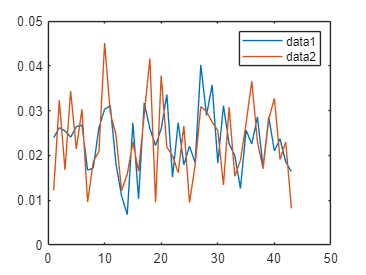

%load("match1.csv");
filename = 'match1.csv'; % 替换为你的CSV文件路径
match1 = readtable(filename);
res1=AHPTOPSIS(match1,1);
res2=AHPTOPSIS(match1,2);
x=1:1:43;
plot(x,res1,x,res2);
legend;

%按照势头预测的正确率
match=data(1:300,:);
won=[];
n=1;
for i=1:height(match)
    if i==height(match)
        won(end+1)=match{i,"game_victor"};
        break;
    end
    if match{i+1,"set_no"}-match{i,"set_no"}~=0
        n=1;
    end
    if match{i+1,"game_no"}-match{i,"game_no"}~=0
        won(end+1)=match{i,"game_victor"};
        n=n+1;
    end
end
won=won';

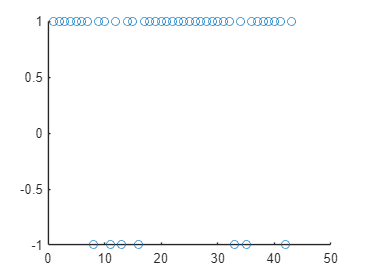

diff=res1-res2;
corrcet=[];
for i=1:length(diff)
    if diff(i)*(won(i)-1.5)<0
        corrcet(i)=1;
    else
        corrcet(i)=-1;
    end
end
scatter(1:1:43,corrcet)

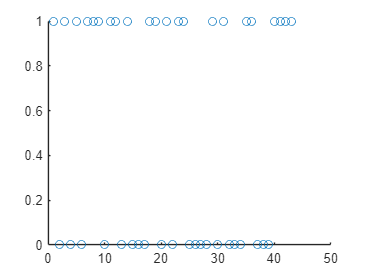

%发球时赢为1，看一下发球获胜率用的
c=[];
for i=1:43
    if match{i,"server"}==won(i)
        c(i)=1;
    else
        c(i)=0;
    end
end
scatter(1:1:43,c)